## Aula inaugural de Emc 307

### Tópicos

### Boas prátiacas

clc;                %limpa a tela
clear all;          %limpa as variaveis
close all;          %fecha as figuras

### Trabalhando com variavel simbólica


$$f(x) = \int_{0}^{1} xdx$$


syms x;                         %define x como simbólica
resultado = int(x,x,0,1);       %faz a integral de x em x
resultado = eval(resultado);    %transforma resultado em numerioco

### Lendo um arquivo wav e visualizando

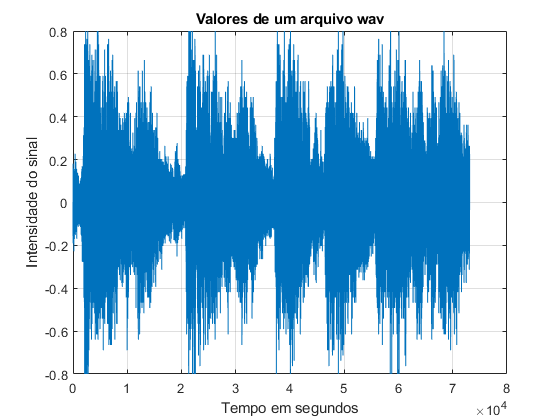

load handel                         %lê um arquivo wav

figure(1)                           %cria uma nova figura

plot(y);                            %cria um gráfico de amplitude


grid;                               %cria um reticulado
xlabel('Tempo em segundos')         %legenda do eixo x
ylabel('Intensidade do sinal')      %legenda do eixo y
title('Valores de um arquivo wav')  %titulo do grafico

### Criando uma função handle e visualizando


$$f(x,y) = x^2 + y^2$$


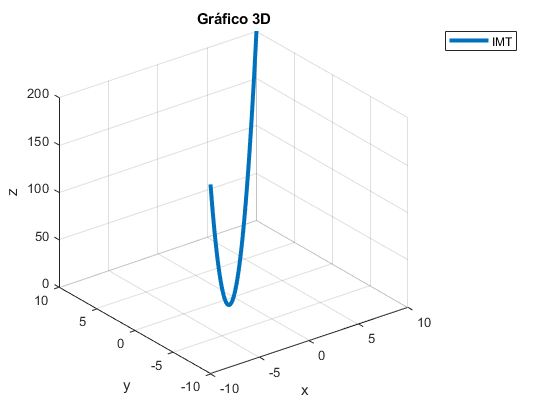

tic;                                    %começa o relogio
z = @(x,y) x.^2 + y.^2;                 %cria uma função handle
x = [-10:0.1:10];                       %cria u vetor de dados x
y = [-10:0.1:10];                       %cria um vetor de dados y

figure()                                %cria uma nova figura

plot3(x,y,z(x,y), 'linewidth', 3);      %cria o grafico
legend("IMT")                           %legenda
grid;                                   %cria um reticulado
ylabel("y")                             %legenda do y
xlabel("x")                             %legenda do x
zlabel("z")                             %legenda do z
title("Gráfico 3D")                     %titulo do grafico

toc                                 %para o relogio

Elapsed time is 0.355178 seconds.


### Problema 1

syms t;
c = [0:0.1:2];
J = @(t) int(c*1*sin(t),t,0,pi) + int(c*-1*sin(t),t,pi,2*pi);
J(t)

$$ans = \left(\begin{array}{ccccccccccccccccccccc} 0 & \frac{2}{5} & \frac{4}{5} & \frac{6}{5} & \frac{8}{5} & 2 & \frac{12}{5} & \frac{14}{5} & \frac{16}{5} & \frac{18}{5} & 4 & \frac{22}{5} & \frac{24}{5} & \frac{26}{5} & \frac{28}{5} & 6 & \frac{32}{5} & \frac{34}{5} & \frac{36}{5} & \frac{38}{5} & 8 \end{array}\right)$$

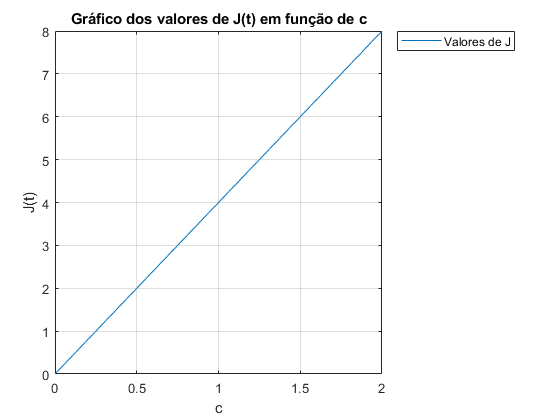

plot(c,J(t))
legend("Valores de J")                           %legenda
grid;                                   %cria um reticulado
ylabel("J(t)")                             %legenda do y
xlabel("c")                             %legenda do x                             %legenda do z
title("Gráfico dos valores de J(t) em função de c")                     %titulo do grafico